# **Lab#1 Modelling of mechanics of the actuators**

## 1.0. Initial conditions

Ua = 400;
Ra = 21.45;
dfi = 0.39; 

Trated = 100;
Ta = 3e-3;
T1 = 60;
T2 = 40;
Ke = 15;
KT = Ke;
J1 = 1.72;
J2 = 0.7;
k12 = 7846;

wr1 = sqrt(k12*(J1+J2)/J1/J2);
av = 3*wr1/10/pi;
b12 = 2*av*J1*J2/(J1+J2);

## 1.1. Research process in a model

Tref = 0.1*Trated;
Tmdl = 10;

warning off
Simout = sim('lab1s2022a.slx','ReturnWorkspaceOutputs','on');
warning on

### Transient response of w1and w2

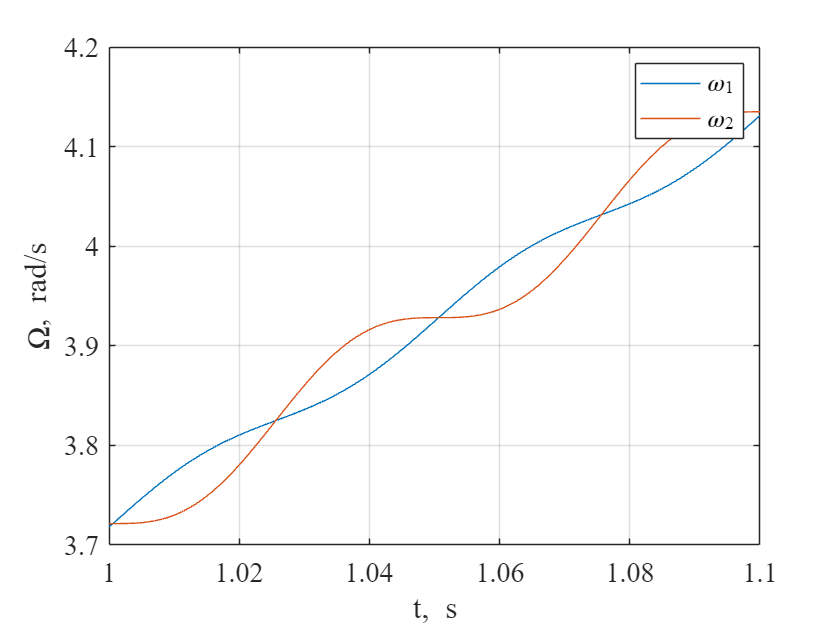

t = Simout.tout(:,1);
w1 = Simout.ScopeData(:,2);
w2 = Simout.ScopeData(:,3);

h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(t,w1)
    grid on
    hold on
    plot(t,w2)
    ylabel('\Omega, \itrad\rm/\its')
    xlabel('\itt\rm, \its')
    legend('\omega_1','\omega_2')
    xlim([1 1.1])

### Transient response of A12

t = Simout.ScopeData2(:,1);

位置 2 处的索引超出数组边界。

A1 = Simout.ScopeData2(:,2);

h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(t,A1)
    grid on
    hold on
    ylabel('A_{1}, \itNm')
    xlabel('\itt\rm, \its')
    xlim([1 1.1])
    A2 = Simout.ScopeData2(:,3);

h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(t,A2)
    grid on
    hold on
    ylabel('A_{2}, \itNm')
    xlabel('\itt\rm, \its')
    xlim([1 1.1])

### Transient response of T12

t = Simout.ScopeData(:,1);
T12 = Simout.ScopeData(:,4);

h = figure;
    set(h,'DefaultAxesFontSize',14);
    set(h,'DefaultAxesFontName','Times New Roman');
    plot(t,T12)
    grid on
    hold on
    ylabel('T_{12}, \itNm')
    xlabel('\itt\rm, \its')
    xlim([1 1.1])

## 1.2. Research the effect of backlash in a model of the two-mass mechanism

### Transient response of T12

## 1.3. Design a model of the two-mass mechanism with viscous frictions

    av = 3*wr1/10/pi;
    b12 = 2*av*J1*J2/(J1+J2);


## part 2

J1 = 1.72;
% J2 = J1*1;
k12 = 9000; % 5000 7500 9000
% %Ra = 200;
% %Ke = 200;
% Ta = 3e-2;